# Tune Tracking Filter Using Tuning Data Generated from Tracking Scenario

Instantiate the filter with the first detection - give it a reasonable starting point.

filter = initcaekf(initialDetection);

Create a `trackingFilterTuner` object and set its `Display` property to `"Plot"`.

tuner = trackingFilterTuner('Display',"Plot",'Cost','NEES',...
    'FilterInitializationFcn','initcaekf',...
    'Solver','fmincon');
tuner.SolverOptions = optimoptions("fmincon",MaxIterations=100); % Increase max
tps = tunableProperties(filter)

tps = Tunable properties for object of type: trackingEKF

Property:      ProcessNoise
   PropertyValue:   [1 0 0;0 1 0;0 0 1]
   TunedQuantity:   Square root
   IsTuned:         true
       TunedQuantityValue:  [1 0 0;0 1 0;0 0 1]
       TunableElements:     [1 4 5 7 8 9]
       LowerBound:          [0 0 0 0 0 0]
       UpperBound:          [10 10 10 10 10 10]
Property:      StateCovariance
   PropertyValue:   [3428180378.0423 0 0 0 0 0 0 0 0;0 100 0 0 0 0 0 0 0;0 0 100 0 0 0 0 0 0;0 0 0 3428180378.0423 0 0 0 0 0;0 0 0 0 100 0 0 0 0;0 0 0 0 0 100 0 0 0;0 0 0 0 0 0 3428180378.0423 0 0;0 0 0 0 0 0 0 100 0;0 0 0 0 0 0 0 0 100]
   TunedQuantity:   Square root of initial value
   IsTuned:         false


Based on the display, the tuner tunes only the ProcessNoise property, which is a 3-by-3 matrix. Change the tunable elements to be only the diagonal elements by using the setPropertyTunability object function. Set the lower and upper bounds for tuning the diagonal elements.

setPropertyTunability(tps,"ProcessNoise",TunableElements=[1 5 9], ...
    LowerBound=[1e-9 1e-9 1e-9],UpperBound = [1e-1 1e-1 1e-1])
setPropertyTunability(tps,"StateCovariance",IsTuned=true);

Set the tuned elements for the state covariance matrix as the diagonal elements with specified bounds.

% Set ranges according to approx values
upperStateCov = [1e9, 1e3,10,...
    10e9,1e3,10,...
    10e9,1e3,10];
% Square to make them covariance terms
upperStateCov=upperStateCov.^2;

% Set ranges according to approx values
lowerStateCov = [10e3, 0,0,...
    10e3, 0,0,...
    10e3, 0,0];
% Square to make them covariance terms
lowerStateCov = lowerStateCov.^2;

% Define indices for tuning
indices = sub2ind([9,9],1:9,1:9);

setPropertyTunability(tps,"StateCovariance",TunableElements=indices, ...
    LowerBound=lowerStateCov,UpperBound=upperStateCov);

disp(tps)

Tunable properties for object of type: trackingEKF

Property:      ProcessNoise
   PropertyValue:   [1 0 0;0 1 0;0 0 1]
   TunedQuantity:   Square root
   IsTuned:         true
       TunedQuantityValue:  [1 0 0;0 1 0;0 0 1]
       TunableElements:     [1 5 9]
       LowerBound:          [1e-09 1e-09 1e-09]
       UpperBound:          [0.1 0.1 0.1]
Property:      StateCovariance
   PropertyValue:   [3428180378.0423 0 0 0 0 0 0 0 0;0 100 0 0 0 0 0 0 0;0 0 100 0 0 0 0 0 0;0 0 0 3428180378.0423 0 0 0 0 0;0 0 0 0 100 0 0 0 0;0 0 0 0 0 100 0 0 0;0 0 0 0 0 0 3428180378.0423 0 0;0 0 0 0 0 0 0 100 0;0 0 0 0 0 0 0 0 100]
   TunedQuantity:   Square root of initial value
   IsTuned:         true
       TunedQuantityValue:  [58550.6650520923 0 0 0 0 0 0 0 0;0 10 0

To enable custom tunable properties, set the TunablePropertiesSource and CustomTunable properties to "Custom" and tps, respectively.

tuner.TunablePropertiesSource = "Custom";
tuner.CustomTunableProperties = tps;

**Load and Reformat data for Tuner**

Load the the data from our scenario.

S = load('SpaceDebrisLEO_1Target.mat');
truthPos = S.truthPos; % Truth Position - where the target actually is
detPos = S.detPos;     % Detection Position - where the target was detected
time = S.time;
objDet = S.objDet;
truthVel = S.truthVel;
speed = S.speed;
initialDetection = objDet{1};

Reformat data for tune input:

Time = time';
Position = truthPos';
truthTable = table(Time,Position);

**Perform Tuning**

Tune the tracking filter based on the tuning data.

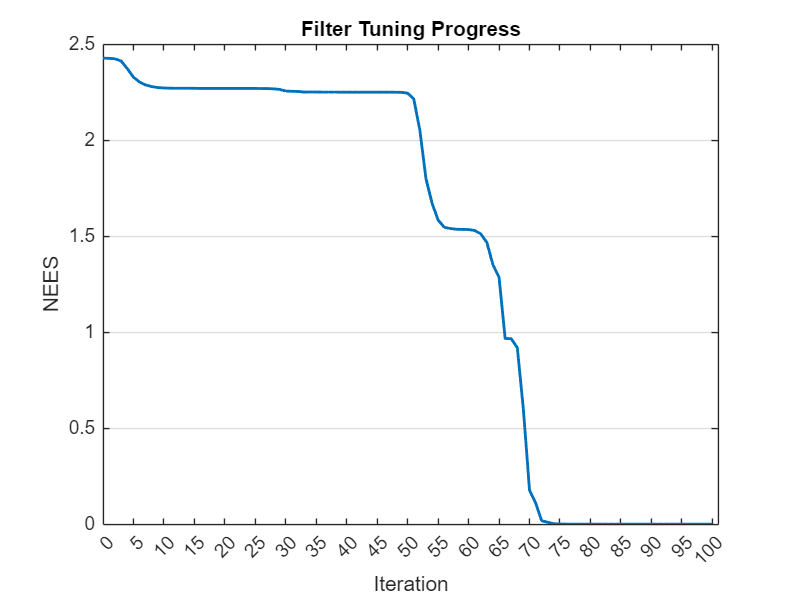


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+02.



tunedProps = struct with fields:
       ProcessNoise: [3×3 double]
    StateCovariance: [9×9 double]


tunedProps = tune(tuner,objDet,truthTable)

Generate the filter initialization function after tuning by using the `exportToFunction` object function.

exportToFunction(tuner,"tunedInitFcn_CA")

Obtain the tuned filter by evaluating the tuned initialization function on an object detection. Show the tuned process noise.

tunedFilter = tunedInitFcn_CA(objDet{1})

tunedFilter =   trackingEKF with properties:

                          State: [9×1 double]
                StateCovariance: [9×9 double]

             StateTransitionFcn: @constacc
     StateTransitionJacobianFcn: @constaccjac
                   ProcessNoise: [3×3 double]
        HasAdditiveProcessNoise: 0

                 MeasurementFcn: @cameas
         MeasurementJacobianFcn: @cameasjac
         HasMeasurementWrapping: 1
               MeasurementNoise: [3×3 double]
    HasAdditiveMeasurementNoise: 1

                MaxNumOOSMSteps: 0

                EnableSmoothing: 0


tunedFilter.ProcessNoise

ans = 1.0e-06 *

    0.2500         0         0
         0    0.2500         0
         0         0    0.2500


posIdx = indices(1:3:end);
veloIdx = indices(2:3:end);
pos = tunedFilter.StateCovariance(posIdx)

pos = 1.0e+16 *

    1.0000    1.0000    1.0000


velo = tunedFilter.StateCovariance(veloIdx)

velo = 1.0e+06 *

    5.0192    0.0117    3.8305


*Copyright 2022 The MathWorks, Inc.*